# Transfer Learning with Pretrained Audio Networks in Deep Network Designer

## Add Path

addpath("AirCompressorDataset")
addpath("yamnet")

## Load Data

Create an `audioDatastore` object to manage the data. 

ads = audioDatastore('AirCompressorDataset',IncludeSubfolders=true,LabelSource="foldernames");

Split the data into training, validation, and test sets using the `splitEachLabel` function.

[adsTrain,adsValidation,adsTest] = splitEachLabel(ads,0.7,0.2,0.1);

Use the `transform` function to preprocess the data using the function `audioPreprocess`, found at the end of this example. For each signal: 

- Use [`yamnetPreprocess`](docid:audio_ref#mw_bc2966eb-df69-4f8f-b8fc-33b8a4c2b63e) to generate mel spectrograms suitable for training using YAMNet. Each audio signal produces multiple spectrograms.

- Duplicate the class label for each of the spectrograms.

tdsTrain = transform(adsTrain,@audioPreprocess,IncludeInfo=true);
tdsValidation = transform(adsValidation,@audioPreprocess,IncludeInfo=true);
tdsTest = transform(adsTest,@audioPreprocess,IncludeInfo=true);

## Select Pretrained Network

Prepare and train the network interactively using [**Deep Network Designer**](docid:nnet_ref#mw_301a3a9d-998a-4668-aec4-f94646b76921). To open Deep Network Designer, on the **Apps** tab, under **Machine Learning and Deep Learning**, click the app icon. Alternatively, you can open the app from the command line.

deepNetworkDesigner

Deep Network Designer provides a selection of pretrained audio classification networks. These models require both Audio Toolbox™ and Deep Learning Toolbox™.

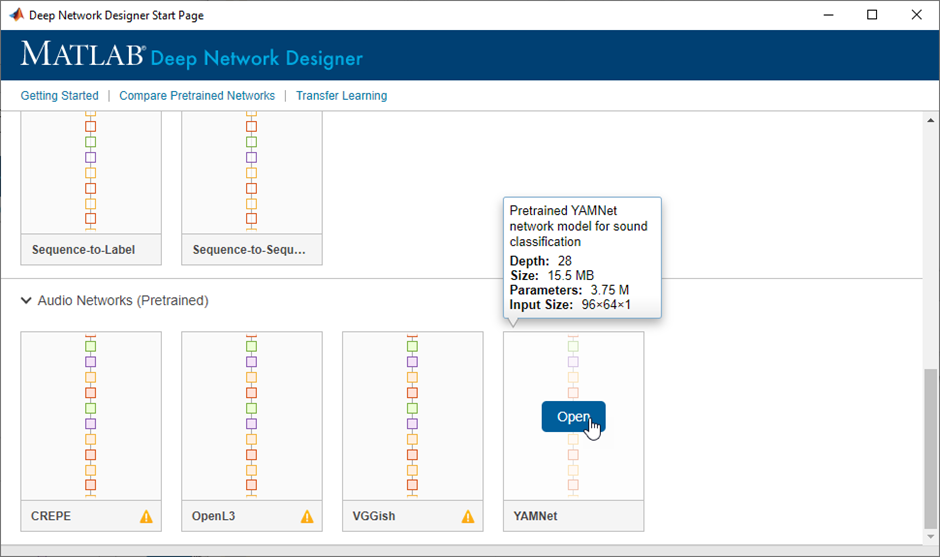

Under **Audio Networks**, select **YAMNet** from the list of pretrained networks and click **Open**. If the Audio Toolbox model for YAMNet is not installed, click **Install** instead. Deep Network Designer provides a link to the location of the network weights. Unzip the file to a location on the MATLAB path. Now close the Deep Network Designer Start Page and reopen it. When the network is correctly installed and on the path, you can click the **Open** button on YAMNet. The YAMNet model can classify audio into one of 521 sound categories. For more information, see [`yamnet`](docid:audio_ref#function_yamnet).

Deep Network Designer displays a zoomed-out view of the whole network in the **Designer** pane. To zoom in with the mouse, use **Ctrl**+scroll wheel. To pan, use the arrow keys, or hold down the scroll wheel and drag the mouse. Select a layer to view its properties. Clear all layers to view the network summary in the **Properties** pane.

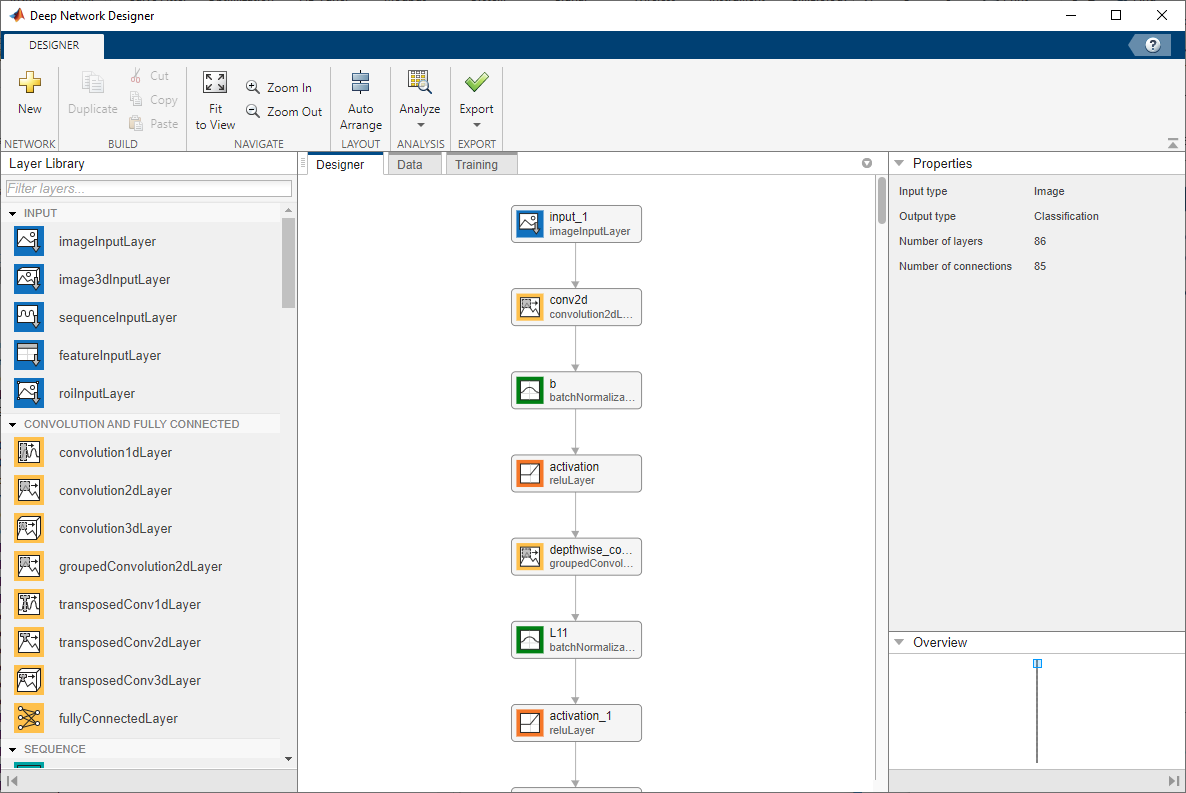

## Prepare Network for Transfer Learning

To prepare the network for transfer learning, in the **Designer** pane, replace the last learnable layer and the final classification layer.

**Replace Last Learnable Layer**

To use a pretrained network for transfer learning, you must change the number of classes to match your new data set. First, find the last learnable layer in the network. For YAMNet, the last learnable layer is the last fully connected layer, `dense`.

Drag a new `fullyConnectedLayer` onto the canvas. The `OutputSize` property defines the number of classes for classification problems. Change `OutputSize` to the number of classes in the new data, in this example, 8.

Change the learning rates so that learning is faster in the new layer than in the transferred layers by setting `WeightLearnRateFactor` and `BiasLearnRateFactor` to `10`.

Delete the last fully connected layer and connect your new layer instead.

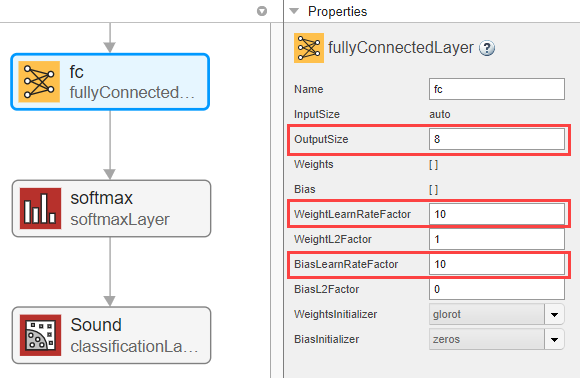

**Replace Output Layer**

For transfer learning, you need to replace the output layer. Scroll to the end of the **Layer Library** and drag a new `classificationLayer` onto the canvas. Delete the original classification layer and connect your new layer in its place.

For a new output layer, you do not need to set `OutputSize`. At training time, Deep Network Designer automatically sets the output classes of the layer from the data.

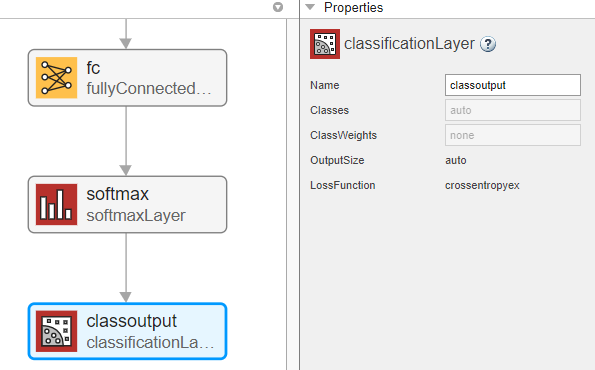

**Check Network**

To check that the network is ready for training, click **Analyze**. If the Deep Learning Network Analyzer reports zero errors, then the edited network is ready for training.

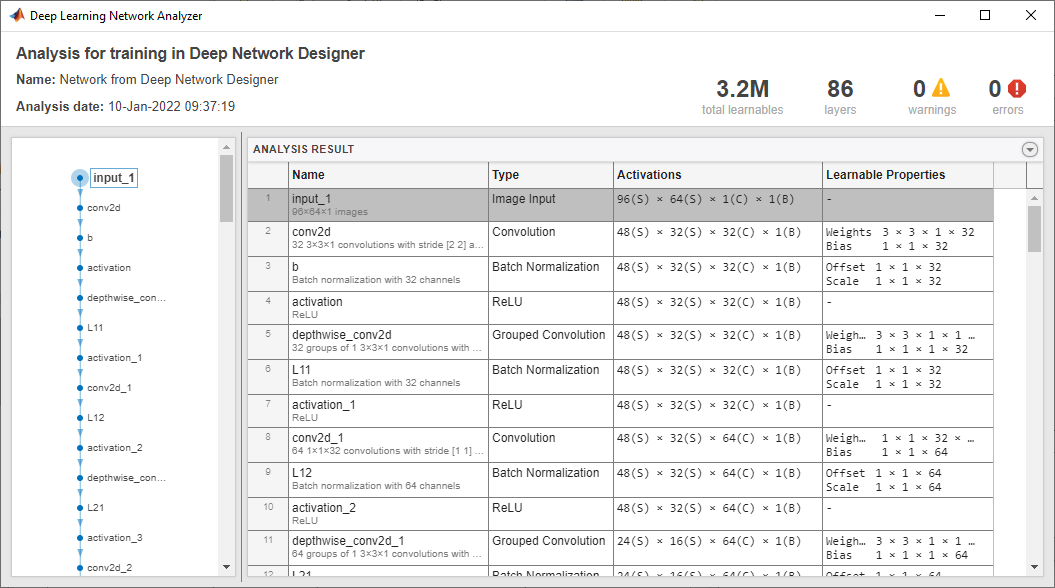

## Import Data

To load the data into Deep Network Designer, on the **Data** tab, click **Import Data** > **Import Datastore**. Select `tdsTrain` as the training data and `tdsValidation` as the validation data.

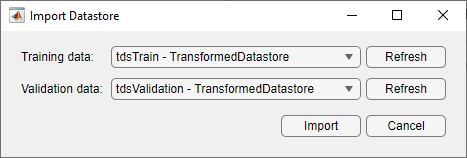

Using Deep Network Designer, you can inspect the training and validation data in the **Data** tab. You can see that the data is as expected prior to training.

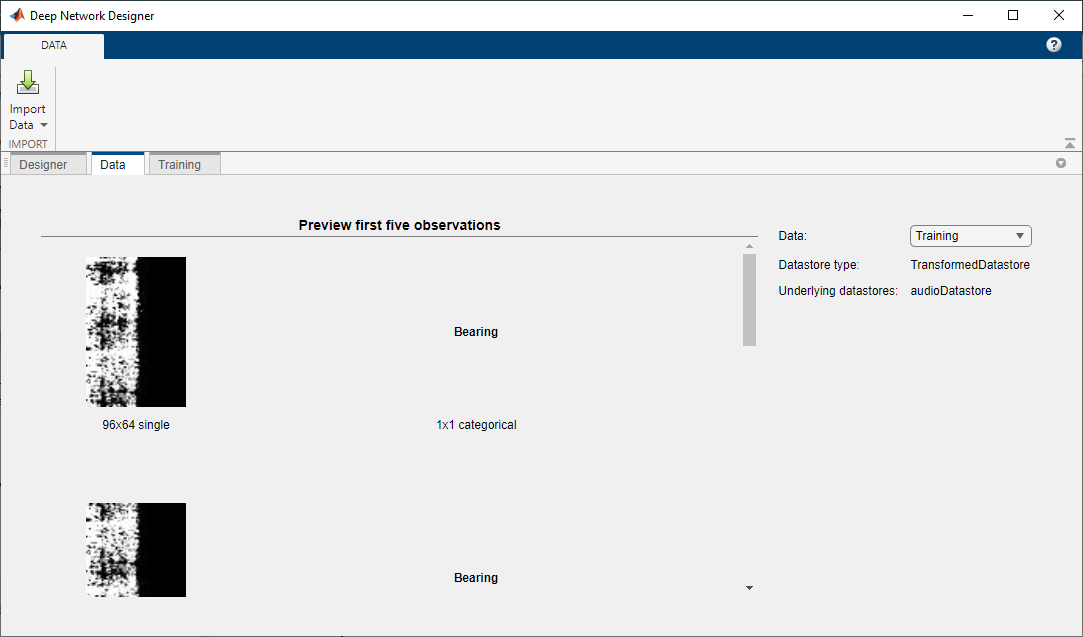

## Select Training Options

To specify the training options, select the **Training** tab and click **Training Options**. Set the initial learning rate to a small value to slow down learning in the transferred layers. In combination with the increased learning rate factors for the fully connected layer, learning is now fast only in the new layers and slower in the other layers. 

For this example, set **Solver** to `adam`, **InitialLearnRate** to `0.0001`, and **MaxEpochs** to 2.

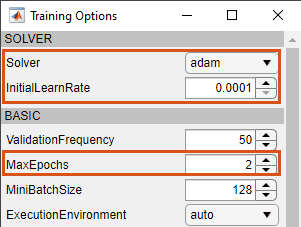

## Train Network

To train the network with the specified training options, click **Close** and then click **Train**.

Deep Network Designer allows you to visualize and monitor the training progress. You can then edit the training options and retrain the network, if required. To find the optimal training options, create a deep learning experiment using Experiment Manager. You can create a deep learning experiment in Deep Network Designer by clicking **Export** > **Create Experiment**.

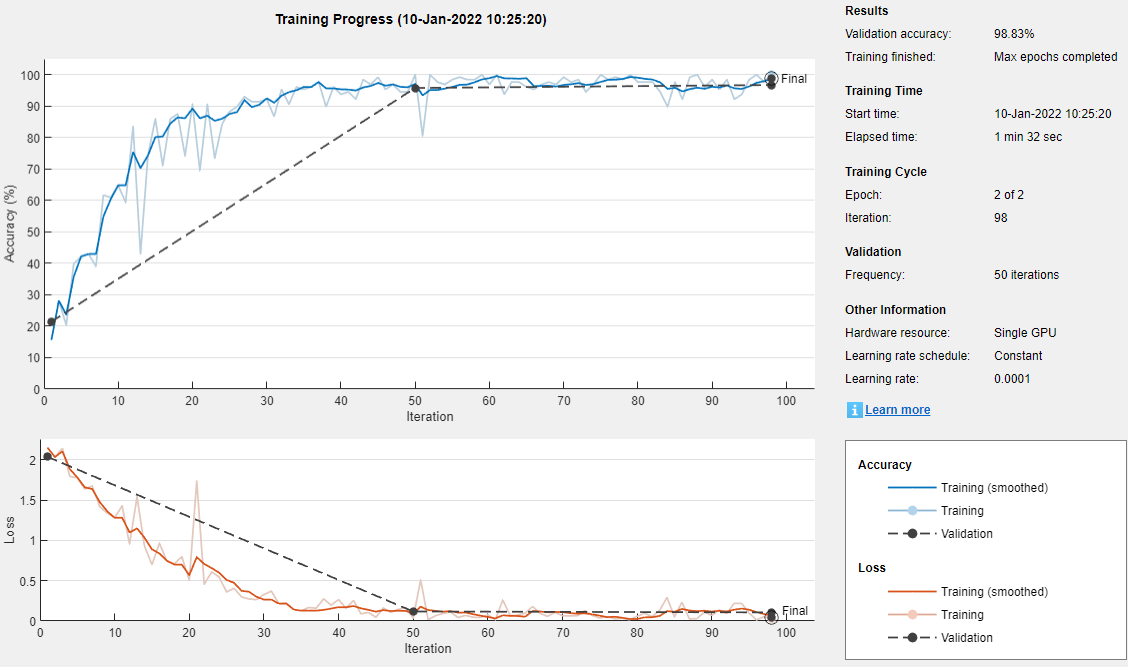

To export the results from training, on the **Training** tab, select **Export** > **Export Trained Network and Results**. Deep Network Designer exports the trained network as the variable `trainedNetwork_1` and the training info as the variable `trainInfoStruct_1`.

You can also generate MATLAB code, which recreates the network and the training options used. On the **Training** tab, select **Export** > **Generate Code for Training**. Examine the MATLAB code to learn how to programmatically prepare the data for training, create the network architecture, and train the network.

## Test Network

Classify the test data using the exported network and the `classify` function.

%create the test ground truth
data = readall(tdsTest);
YTest = [data{:,2}];

%use classify function to classify the data
YPred = classify(trainedNetwork_1,tdsTest);

Unrecognized function or variable 'trainedNetwork_1'.

%see the accuracy of the model
accuracy = sum(YPred == YTest')/numel(YTest)

## Supporting Function - Generate Spectrograms 

The function `audioPreprocess` uses [`yamnetPreprocess`](docid:audio_ref#mw_bc2966eb-df69-4f8f-b8fc-33b8a4c2b63e) to generate mel spectrograms from `audioIn` that you can feed to the YAMNet pretrained network. Each input signal generates multiple spectrograms, so the labels must be duplicated to create a one-to-one correspondence with the spectrograms.

function [data,info] = audioPreprocess(audioIn,info)
class = info.Label;
fs = info.SampleRate;
features = yamnetPreprocess(audioIn,fs);

numSpectrograms = size(features,4);

data = cell(numSpectrograms,2);
for index = 1:numSpectrograms
    data{index,1} = features(:,:,:,index);
    data{index,2} = class;
end
end

## References

[1] Verma, Nishchal K., Rahul Kumar Sevakula, Sonal Dixit, and Al Salour. “Intelligent Condition Based Monitoring Using Acoustic Signals for Air Compressors.” IEEE Transactions on Reliability 65, no. 1 (March 2016): 291–309. https://doi.org/10.1109/TR.2015.2459684.

*Copyright 2021 The MathWorks, Inc.*